# **Worksheet 4 Unconstrained optimization **

**J.Morlier March 2020**

## On the descent direction 

Consider the function f : R2 → R given by J(x) = x1^3+x^2 +2*x2. Give some descent directions for J at the point [1,1]⊤. Is there any descent direction at the point [0, −1]⊤ ? Justify the answer.

clear all; close all;


syms x1 x2 
J=x1^3 +x2^2 +2*x2

$$J = {x_{1}}^{3}+{x_{2}}^{2}+2\,x_{2}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=[dJdx1; dJdx2]

$$dJ = \left(\begin{array}{c} 3\,{x_{1}}^{2}\\ 2\,x_{2}+2 \end{array}\right)$$

substitute with Point (1,1);

A=subs(dJ,[x1 x2], [1 1 ])

$$A = \left(\begin{array}{c} 3\\ 4 \end{array}\right)$$

Create vector of possible descent directions

syms d1 d2 real
dir=A'*[d1; d2]

$$dir = 3\,d_{1}+4\,d_{2}$$

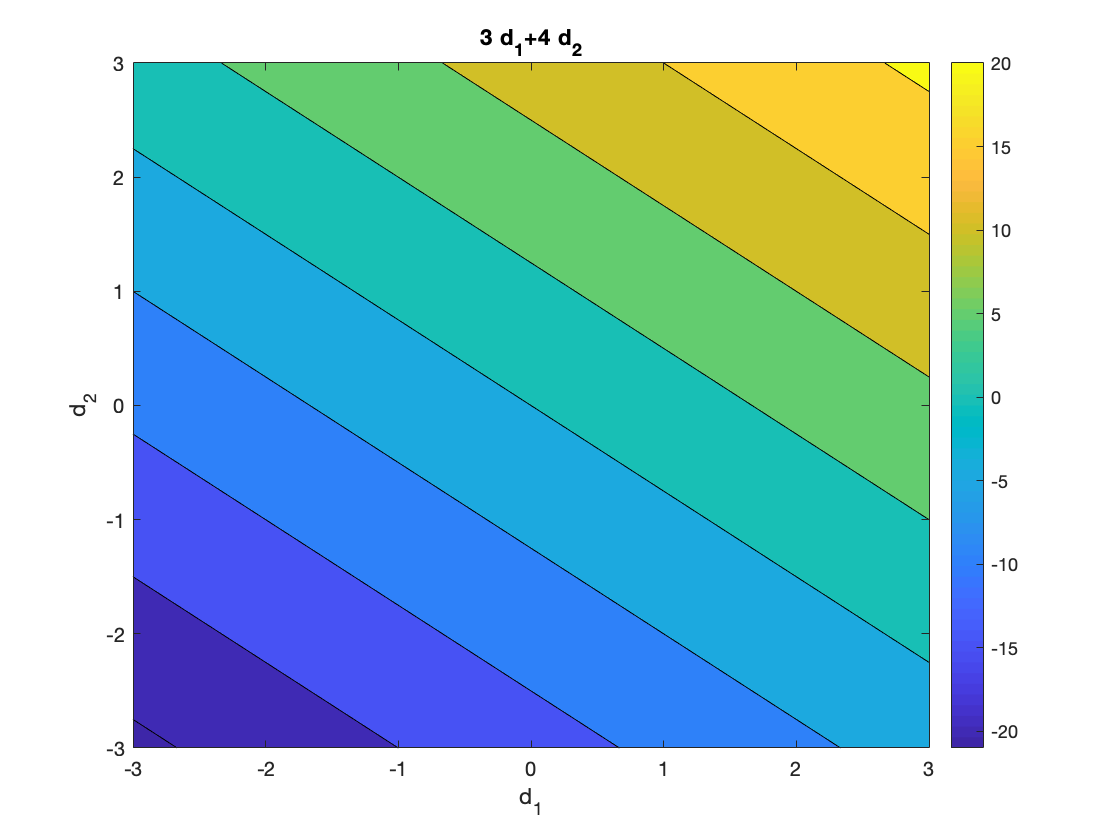

dir = '3*d1+4*d2';
ezcontourf(dir,[-3 3 -3 3]); colorbar;

It's up to you to choose one possible solution	such that 3d1 + 4d2 < 0				

substitute with (0,-1). Something wrong?

A=subs(dJ,[x1 x2], [0 -1 ])

$$A = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

syms d1 d2 real
dir=A'*[d1; d2]

$$dir = 0$$

thus one cannot find a descent direction at the point.

## On the optimal step-size 

Compute the optimal step-size at [5, 1]⊤ following the direction d = −∇f (5, 1). 


syms x1 x2 
J=0.5*x1^2 + 4.5*x2^2

$$J = \frac{{x_{1}}^{2}}{2}+\frac{9\,{x_{2}}^{2}}{2}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=simplify([dJdx1; dJdx2])

$$dJ = \left(\begin{array}{c} x_{1}\\ 9\,x_{2} \end{array}\right)$$

syms alpha real 
d=-dJ

$$d = \left(\begin{array}{c} -x_{1}\\ -9\,x_{2} \end{array}\right)$$

x=[x1;x2]

$$x = \left(\begin{array}{c} x_{1}\\ x_{2} \end{array}\right)$$

newx=x+alpha*d

$$newx = \left(\begin{array}{c} x_{1}-\alpha \,x_{1}\\ x_{2}-9\,\alpha \,x_{2} \end{array}\right)$$

Jnew=subs(J, [x1, x2], [newx(1) ,newx(2)])

$$Jnew = \frac{{\left(x_{1}-\alpha \,x_{1}\right)}^{2}}{2}+\frac{9\,{\left(x_{2}-9\,\alpha \,x_{2}\right)}^{2}}{2}$$


dJda=diff(Jnew,alpha)

$$dJda = -x_{1}\,\left(x_{1}-\alpha \,x_{1}\right)-81\,x_{2}\,\left(x_{2}-9\,\alpha \,x_{2}\right)$$

substitute with [5,1]

A=subs(dJda,[x1 x2], [5 1])

$$A = 754\,\alpha -106$$

alpha_star=106/754

alpha_star = 0.1406

myfun = @(x) 754*x-106;  % parameterized function                   
fun = @(x) myfun(x);    % function of x alone
x_star = fzero(fun,0.1)

x_star = 0.1406

## On the Newton method 

For a given starting point x(0) = [x1, x2]⊤, compute the Newton direction at this point. 

dJ

$$dJ = \left(\begin{array}{c} x_{1}\\ 9\,x_{2} \end{array}\right)$$


Hdx1=diff(dJ,x1);

Hdx2=diff(dJ,x2);

H=[Hdx1 Hdx2]

$$H = \left(\begin{array}{cc} 1 & 0\\ 0 & 9 \end{array}\right)$$

give newton's direction

d_0=-inv(H)*dJ

$$d\_0 = \left(\begin{array}{c} -x_{1}\\ -x_{2} \end{array}\right)$$

it seems always negative? right ? $d_0$ is a descent direction for J at the point x(0) 

xnew=x+d_0				

$$xnew = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Hence, one gets in one iteration the optimal solution independently of the starting point (this is the case for all quadratic minimization problems) 

## Same question with a new function

For a given starting point x(0) = [x1, x2]⊤, compute the Newton direction at this point. 

syms x1 x2 
J=x1^4 + 2*x2^2

$$J = {x_{1}}^{4}+2\,{x_{2}}^{2}$$

dJdx1=diff(J,x1)  ;

dJdx2=diff(J,x2) ;

dJ=simplify([dJdx1; dJdx2])

$$dJ = \left(\begin{array}{c} 4\,{x_{1}}^{3}\\ 4\,x_{2} \end{array}\right)$$

Hdx1=diff(dJ,x1);

Hdx2=diff(dJ,x2);

H=[Hdx1 Hdx2]

$$H = \left(\begin{array}{cc} 12\,{x_{1}}^{2} & 0\\ 0 & 4 \end{array}\right)$$

give newton's direction

d_0=-inv(H)*dJ

$$d\_0 = \left(\begin{array}{c} -\frac{x_{1}}{3}\\ -x_{2} \end{array}\right)$$

it seems always negative? right ? $d_0$ is a descent direction for J at the point x(0) 

xnew=x+d_0				

$$xnew = \left(\begin{array}{c} \frac{2\,x_{1}}{3}\\ 0 \end{array}\right)$$

One iteration of the Newton method is not enough to converge to the optimal solution. 